# Aircraft trim (simplified)

from jetdemo.m

A simplified trim model of the aircraft during cruise flight 


$$\frac{dx}{dt} = Ax + Bu$$



$$y = Cx + Du$$


has four states:

  beta (sideslip angle), phi (bank angle), yaw rate, roll rate

and two inputs: 

     the rudder and aileron deflections. 

All angles and angular velocities are in radians and radians/sec.

A=[-.0558 -.9968 .0802 .0415;
     .598 -.115 -.0318 0;
    -3.05 .388 -.4650 0;
        0 0.0805 1 0];

B=[ .00729  0;
   -0.475   0.00775;
    0.153   0.143;
     0      0];

C=eye(4);

D=0;

sys_plane = ss(A,B,C,D);

%%
% and label the inputs, outputs, and states:
set(sys_plane, 'inputname', {'rudder' 'aileron'},...
         'outputname', {'beta' 'yaw' 'roll' 'phi'},...
         'statename', {'beta' 'yaw' 'roll' 'phi'});
sys_plane

## Analyse de la commandabilité

`Démonter que le système est commandable.`

rank(ctrb(sys_plane))

Le système est commandable avec les entrées de commande mais que ce passe-t-il si on utilise uniquement les ailerons ou le palonnier (rudder) ?

Pour étudier cela, il faut supprimer dans la matrice B les éléments concernant la commande correspondante ou alors utiliser la syntaxe:

sys_aileron = sys_plane(:,'aileron')

sys_rudder = sys_plane(:,'rudder')
rank(ctrb(sys_plane(:,'rudder')))

`Calculer le rang de la matrice de commandabilité.`

rank(ctrb(sys_aileron))
rank(ctrb(sys_rudder))

On en conclu que le système est commandable avec un seul actionneur. Pourquoi en installer deux sur un avion ?

## Cahier des charges

On souhaite piloter le yaw_rate en priorité.

`Analysez le comportement du système (stabilité, temps de réponse et oscillations).`

eig(sys_plane.A)
% Le système est stable car toutes ces valeurs propres ont des parties
% réeles strictement négatives

% Re(\lambda_4) = -0.0073 ce qui correspond à un temps de convergence de 6.8493
% min

% Le systeme va bcp oscillé avant de se stabiliser. Mais les oscillation
% s'attenueront avant que le systeme converge (91s)

On constate que le système est très oscillant et lent (7 minutes pour atteindre le régime permanent ). On va se fixer un temps de réponse de 10s  coefficient d'amortissement de 0.7 (éviter 1 pour les problèmes numériques)

On se fixe comme pôle en boucle fermée :

[Wn,Z,P] = damp(sys_plane);
xi = 0.7;
wn = Wn(3);
p3 = -xi*wn+wn*1i*sqrt(1-xi^2);
Pbut = [-3/10,P(2), p3, p3'];
%Pbut = P;

`Justifier ces choix.`

% Le calcul de p3 permet de reconstruire la valeur prpore 3 (celle qui
% ocille) mais en changeant la pulsation wn

% -3/10 est un vp qui correpond a un temps de convergence de 10s (à 95%) et
% zeta = 1

% P(2) correspond a la vp la plus rapide qui a déja un temps de convergence
% de 5.3s

% p3 et p3' sont les 2 vp conjuguées de pulsation wn (la meme que
% precedement, suffisemment rapide) et coef d'amortissement 0.7

## Commande à l'aide de l'aileron

`Concevoir un retour d'état simple asservir le yaw_rate avec l'aileron. S'inspirer des commandes suivantes :`

sys_aileron = sys_plane(:,'aileron')


sys_aileron =
 
  A = 
            beta      yaw     roll      phi
   beta  -0.0558  -0.9968   0.0802   0.0415
   yaw     0.598   -0.115  -0.0318        0
   roll    -3.05    0.388   -0.465        0
   phi         0   0.0805        1        0
 
  B = 
         aileron
   beta        0
   yaw   0.00775
   roll    0.143
   phi         0
 
  C = 
         beta   yaw  roll   phi
   beta     1     0     0     0
   yaw      0     1     0     0
   roll     0     0     1     0
   phi      0     0     0     1
 
  D = 
         aileron
   beta        0
   yaw         0
   roll        0
   phi         0
 
Continuous-time state-space model.


[A,B,C,D] = ssdata(sys_aileron);
C_yaw = sys_aileron('yaw',:).C;


K = place(A, B, Pbut)

K =   -66.4580 -120.8557   17.4098    6.8273


G = C_yaw * ((A - B*K) \ B)

G = -0.0299

Afin de pouvoir tracer la valeur de la commande, on utiliser la définition suivante pour le système en boucle fermée.

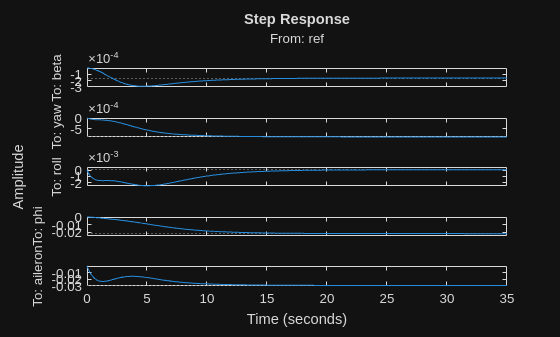

sys_bf_aileron = ss(A-B*K,B*G,[C;K],0);

set(sys_bf_aileron, 'inputname', {'ref'},...
         'outputname', {'beta' 'yaw' 'roll' 'phi','aileron'},...
         'statename', {'beta' 'yaw' 'roll' 'phi'});
     
step(sys_bf_aileron)

`Expliquer le code.`

% On affiche la réponse des états du systeme en boucle fermé à un step. 

% On a pris B*G comme matrice des entrées de telle sorte que B*G*r corrige
% l'erreur statique

## **Commande à l'aide du palonnier**

`Même chose avec le palonnier`

sys_pal = sys_plane(:,'rudder')


sys_pal =
 
  A = 
            beta      yaw     roll      phi
   beta  -0.0558  -0.9968   0.0802   0.0415
   yaw     0.598   -0.115  -0.0318        0
   roll    -3.05    0.388   -0.465        0
   phi         0   0.0805        1        0
 
  B = 
          rudder
   beta  0.00729
   yaw    -0.475
   roll    0.153
   phi         0
 
  C = 
         beta   yaw  roll   phi
   beta     1     0     0     0
   yaw      0     1     0     0
   roll     0     0     1     0
   phi      0     0     0     1
 
  D = 
         rudder
   beta       0
   yaw        0
   roll       0
   phi        0
 
Continuous-time state-space model.


[A,B,C,D] = ssdata(sys_pal);
C_roll = sys_pal('roll',:).C;


K = place(A, B, Pbut)

K =     0.9849   -3.2290    0.0784    0.0196


G = C_roll * ((A - B*K) \ B)

G = -0.0299

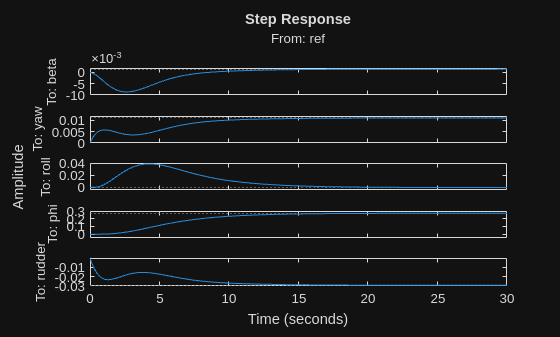

sys_bf_pal = ss(A-B*K,B*G,[C;K],0);

set(sys_bf_pal, 'inputname', {'ref'},...
         'outputname', {'beta' 'yaw' 'roll' 'phi','rudder'},...
         'statename', {'beta' 'yaw' 'roll' 'phi'});
     
step(sys_bf_pal)

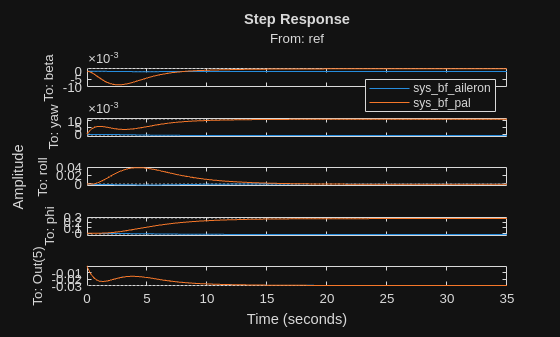

step(sys_bf_aileron,sys_bf_pal)
legend

On arrive bien à piloter la vitesse de rotation de l'avion. On obtient globalement les mêmes performances sauf pour beta. Beta représente le glissement latéral. La valeur idéale de cette grandeur est 0 pour lors d'un virage cela permet d'améliorer le confort et réduire la trainée. Lors d'un atterrissage par vent latéral, le beta doit être contrôlé pour permettre d'aligner l'appareil à la piste.

## Systèmes MIMO

Pour pouvoir piloter deux variables en même temps, il est indipensable d'avoir autant d'entrées de commandes. En effet, il n'y a que dans ce cas où la matrice -(C*(A-B*K)^-1*B) est carré (et donc potentiellement inversible) .

Pour comprendre le problème du placement de pôle sur un système MIMO (mutlti-input multi-output) il faut faire les calculs 'à la main' ... ou alors utiliser la symbolic toolbox de matlab.

Pour déclarer des variables symboliques, il faut écrire :

K = sym('k',[2,4])

Maintenant on peut essayer de calculer le polynôme charactéristique de la boucle fermée dans le cas où on utilise les deux canaux commandes.

[A,B,C,D] = ssdata(sys_plane);
charpoly(A-B*K,'s')
% vpa pour y voir plus clair en ne gardant que 2 chiffres significatifs
vpa(ans,2)

On constate que si on veut identifier les coefficients avec le polynôme but

coef = poly(Pbut) % les coefs du polynome qui a pour racines Pbut
vpa(poly2sym(coef),2)

On a 4 équations et 8 inconnues... donc une infinité de solutions.

La fonction place dans le cas MIMO choisira une qu'il condère optimale (mais peut-être pas nous).

`Calculer un retour d'état dans le cas avec les deux actionneurs grâce à la fonction 'place'.`

[A,B,C,D] = ssdata(sys_plane);
K = place(A,B,Pbut);
C_yaw_beta = sys({'yaw';'beta'},:).C;
%...


On arrive maintenant à faire un virage coordonée mais beta subi un pic au démarage. On considère donc que le choix faire par 'place' ne correspond pas à nos besoin.

## `Méthode LQ`

`Regarder la vidéo sur le LQR.`

[lien vers la vidéo](https://www.youtube.com/watch?v=1_UobILf3cc)

On utilise maintenant la méthode de réglage LQR

help lqr

La méthode LQ permet de minimiser un critère energétique (au sens signal). Elle présente l'avantage d'être interprétable physiquement (contrairement au placement de pôles). En effet, si on augmente le poids d'une variable, elle aura tendance à rester plus proche de sa valeur finale. exemple si 

$Q=\left\lbrack \begin{array}{cccc}
10 &  &  & 0\\
 & 1 &  & \\
 &  & 1 & \\
0 &  &  & 1
\end{array}\right\rbrack$ fera converger plus vite $x_1 ²$ que $Q=\left\lbrack \begin{array}{cccc}
1 &  &  & 0\\
 & 1 &  & \\
 &  & 1 & \\
0 &  &  & 1
\end{array}\right\rbrack \ldotp$

Elle présente aussi l'avantage de permettre la priorisation des cannaux de commande. Par exemple :

$R=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 10
\end{array}\right\rbrack$ pénalisera la commande $u_2$ par rapport à $R=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 10
\end{array}\right\rbrack$.

Par contre on perd la notion de temps. Il est difficile de prédire le temps de réponse. Mais on peut agir dessus tout de même. En effet le rapport $\frac{\left\|Q\right\|}{\left\|R\right\|}$ indique quelle est l'amplitude de la commande par rapport à l'amplitude de l'état. La conséquence est que si les poids de $R$ diminuent, la commande peut être plus grande et donc faire converger le système plus vite. Au contraire, on augmente les poids sur les signaux de commande jugés trop ample.

Cette méthode est itérative. En général on commence soit avec 

$Q=I$ et $R=I$ 

soit on commence en pondérant la diagonale des matrices avec $\frac{1}{\textrm{max²}}$ max étant la norme maximale souhaitée pour le signal en question.

Puis on ajuste les coefficients en fonction des observations. Cette méthodes est très puissante et permet de gérer des situaitons complexes mais demande de l'expérience pour réussir à trouver le réglage 'parfait' rapidement.

On va commencer le réglage avec :

Q = diag([1 1 1 1])
R = diag([1 1])

`Pourquoi Q est 4x4 et R 2x2 ?`

`Ecrire le code pour calculer le gain K avec la méthode LQ ('lqr').`

`Tracer la réponse indicielle et la comparer à la solution par placement de pôle.`

%
%
%


Du premier coup, on fait mieux (c'est de la chance).

On va donner plus d'importance à beta (1000). 

`Changer la matrice Q pour donner un poids de 1000 à beta et ainsi limiter la déviation de ce signal.`

On peut aussi jouer sur la priorité d'utilisation des actionneurs en changeant les poids de R ou encore accélérer ou ralentir en multipliant la matrice R par une constante (si R est grand on pénaliser les grands signaux de commande).

`'Jouer' Q et R pour comprendre comment les choses évoluent. Garder deux essais montrant que l'on peut prioriser un cannal de commande et que l'on peut ralentir/accélérer le système.`

%
%
%


On constate dans le dernier essai que la commande 'rudder' est plus sollicitée que dans les autres cas.

`Si vous n'etes pas convaincu par l'approche LQ, essayer d'avoir le même résultat avec la commande place`. Même si c'est parfois possible de s'en sortir, l'évolution de la réponse et des couplages entres les différentes variables n'est pas évident.